## 1

p = 0.70 %se esteve na aula anerior

p = 0.7000

f = 0.80 %se faltou

f = 0.8000


Probs = [p f;1-p 1-f];


%a)
m_est1 = [1;0];
Probsa = (Probs*Probs) * m_est1;
P_a = Probsa(1)

P_a = 0.7300


%b)
m_est2 = [0;1];
Probsb = (Probs*Probs) * m_est2;
P_b = Probsb(1)

P_b = 0.7200


%c)
Probsc = Probs^15;
P_c = Probsc(1)

P_c = 0.7273

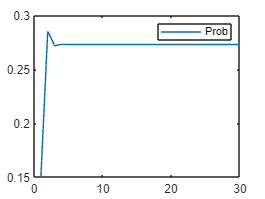


%d)
y = zeros(1,30);
m_est3 = [0.85;0.15];
for i = 1:length(y)
    Matriz = Probs^(i-1)*m_est3;
    y(i) = Matriz(2);
end

plot(1:30,y);
legend("Prob")